# Benchmarking tree-based methods and neural networks

## K-class classification

### Load the cleveland dataset

Recall that the dataset has 5 different classes for disease heart disease severity, where 0 is no disease and 4 is high risk. 

clear all; cleveland = readtable('cleveland.xlsx')

cleveland = 303×14 table
    Age    SEX    chestPain    restingBP    cholest    highBloodSugar    ECG    maxHR    angina0    ECGDepression    slopeST    flouroscopy    thalliumTest    diseaseSeverity
    ___    ___    _________    _________    _______    ______________    ___    _____    _______    _____________    _______    ___________    ____________    _______________

    63      1         1           145         233            1            2      150        0            2.3            3            0              

First, we need to split the dataset into a training and testing set.

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cleveland(:, 1:end-1), cleveland(:, end), ...
    trainingSize, randomstate);

parpool(3)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 3).

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 3
              Cluster: 

Next, we need to standardize the dataset:

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

Next, we'll set the neural network architecutres for the shallow and deep neural networks

snnLayers = [...
    
    sequenceInputLayer(size(Xtrain, 2)), ...            % Input data layer
    
    fullyConnectedLayer(100, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer
    
    fullyConnectedLayer(5, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer                                  % Activation function 1
    
    classificationLayer ...                             % Label encode
];
dnnLayers = [...
    
    sequenceInputLayer(size(Xtrain, 2)), ...            % Input data layer
    
    fullyConnectedLayer(100, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer
    
    dropoutLayer
    
    fullyConnectedLayer(100, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer                                  % Activation function 1
    dropoutLayer
    
    fullyConnectedLayer(100, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer                                  % Activation function 1
    dropoutLayer
    
    fullyConnectedLayer(5, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    softmaxLayer                                  % Activation function 1
    
    classificationLayer ...                             % Label encode
];
options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 2000, ...                        % Maximum number of epochs to train algorithm
    'ValidationData', {Xtest', Ytest'}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress', ...              % Show plots for every epoch
    'ExecutionEnvironment', 'auto' ...
);

### Modeling

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.45963 |    0.040581 |     0.45963 |     0.45963 |           14 |


|    2 | Accept |     0.47826 |    0.033428 |     0.45963 |     0.46129 |           68 |


|    3 | Accept |     0.52795 |    0.039139 |     0.45963 |     0.46545 |            4 |


|    4 | Accept |     0.51553 |    0.037518 |     0.45963 |      0.4676 |            1 |


|    5 | Accept |     0.45963 |    0.040247 |     0.45963 |     0.45963 |           14 |


|    6 | Accept |     0.47826 |    0.032371 |     0.45963 |     0.45963 |           69 |


|    7 | Best   |     0.44099 |    0.035097 |     0.44099 |       0.441 |           22 |


|    8 | Accept |     0.46584 |    0.036391 |     0.44099 |     0.44101 |           27 |


|    9 | Best   |     0.43478 |    0.034266 |     0.43478 |     0.43479 |           19 |


|   10 | Accept |     0.43478 |    0.035583 |     0.43478 |     0.43479 |           19 |


|   11 | Accept |     0.44099 |    0.032047 |     0.43478 |     0.43622 |           20 |


|   12 | Accept |     0.44099 |    0.032574 |     0.43478 |     0.43731 |           18 |


|   13 | Accept |     0.43478 |    0.034106 |     0.43478 |     0.43678 |           19 |


|   14 | Accept |     0.45963 |    0.036169 |     0.43478 |      0.4348 |            8 |


|   15 | Accept |     0.45342 |    0.034204 |     0.43478 |      0.4348 |           10 |


|   16 | Accept |     0.45963 |    0.039479 |     0.43478 |     0.43675 |           12 |


|   17 | Accept |     0.44099 |    0.038162 |     0.43478 |     0.43731 |           20 |


|   18 | Accept |     0.50311 |    0.033441 |     0.43478 |      0.4373 |            2 |


|   19 | Accept |     0.49689 |    0.032072 |     0.43478 |     0.43734 |           43 |


|   20 | Accept |     0.52174 |    0.039801 |     0.43478 |     0.43738 |            3 |


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|   21 | Accept |     0.45963 |    0.037835 |     0.43478 |      0.4372 |            6 |


|   22 | Accept |     0.49689 |    0.040583 |     0.43478 |     0.43723 |           34 |


|   23 | Accept |     0.50311 |     0.03722 |     0.43478 |     0.43716 |            5 |


|   24 | Accept |     0.49689 |    0.032787 |     0.43478 |     0.43716 |           53 |


|   25 | Accept |     0.47826 |    0.031115 |     0.43478 |     0.43717 |           80 |


|   26 | Accept |     0.45963 |    0.034137 |     0.43478 |     0.43718 |            7 |


|   27 | Accept |      0.4472 |    0.043376 |     0.43478 |     0.43717 |            9 |


|   28 | Accept |     0.44099 |    0.033699 |     0.43478 |     0.43482 |           24 |


|   29 | Accept |     0.43478 |    0.034003 |     0.43478 |     0.43481 |           19 |


|   30 | Accept |     0.49689 |    0.035589 |     0.43478 |     0.43481 |           38 |


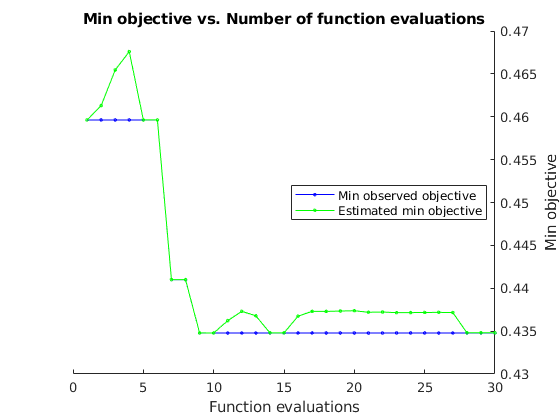

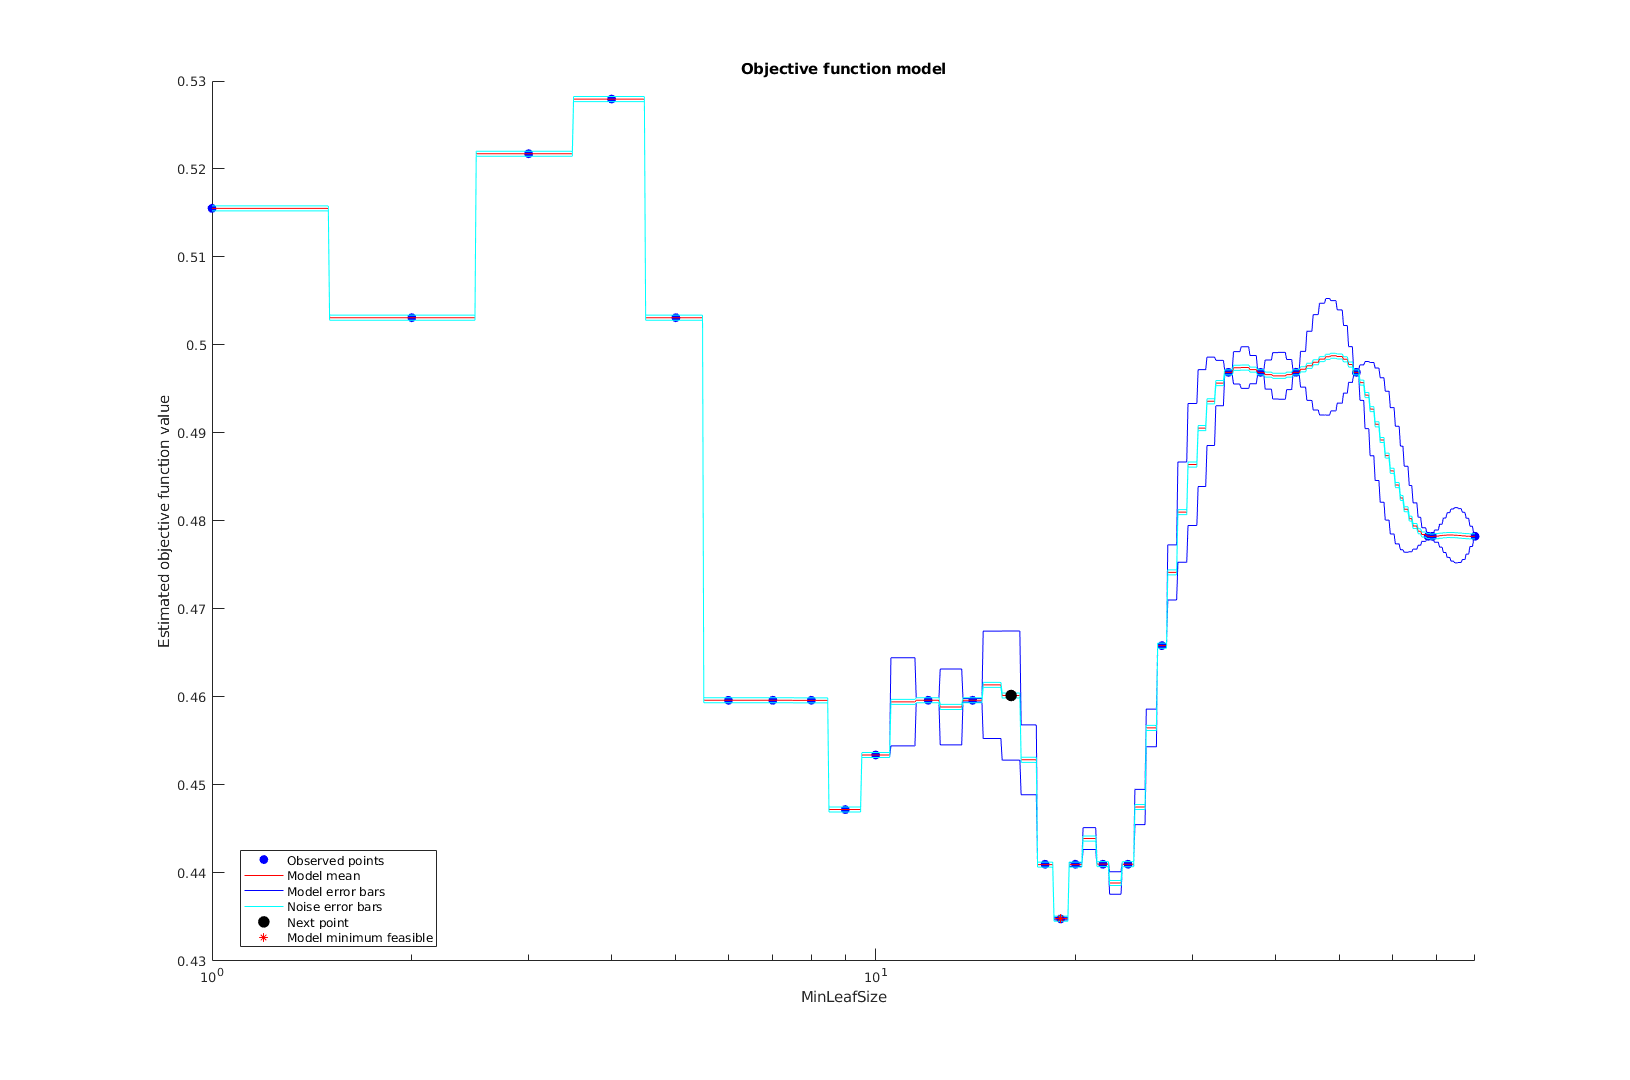


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 23.5061 seconds.
Total objective function evaluation time: 1.077

Best observed feasible point:
    MinLeafSize
    ___________

        19     

Observed objective function value = 0.43478
Estimated objective function value = 0.43481
Function evaluation time = 0.034266

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

        19     

Estimated objective function value = 0.43481
Estimated function evaluation time = 0.035744



Error using trainNetwork (line 170)
Invalid validation data. Responses must be a vector of categorical labels or a cell array of categorical sequences.

kfold = 3; numOfTrees = 100;
idx = crossvalind('kfold', size(Xtrain, 1), kfold);

for i = 1:kfold
    Xtrain2   = Xtrain(idx ~= i, :);
    Ytrain2   = Ytrain(idx ~= i);
    Xtest2    = Xtrain(idx == i, :);
    Ytest2    = Ytrain(idx == i);
    
    % Construct models
    ldaMdl{i}    = fitcdiscr(Xtrain2, Ytrain2);                % Linear Discriminant Analysis
    qdaMdl{i} = fitcdiscr(Xtrain2, Ytrain2, ...           
                         'DiscrimType', 'pseudoQuadratic'); % Quadratic Discriminant Analysis
    logMdl{i} = mnrfit(Xtrain2, categorical(Ytrain2));      % Logistic regression
    dtMdl{i}     = fitctree(Xtrain2, Ytrain2, ...              % Decision trees
                        'OptimizeHyperparameters', 'auto'); 
    rfMdl{i}     = TreeBagger(numOfTrees, ...                  % Random forests
                          Xtrain2, Ytrain2, ...
                          'OOBPrediction', 'on');
    
    NNtrain = Xtrain2'; NNLabels = categorical(Ytrain2');
    [snn{i}, ~] = trainNetwork(NNtrain, NNLabels, ...
        snnLayers, options)
    [dnn{i}, ~] = trainNetwork(NNtrain, NNLabels, ...
        dnnLayers, options)
    
    % Get predictions
    LDAPred2           = predict(ldaMdl{i}, Xtest2);
    QDAPred2           = predict(qdaMdl{i}, Xtest2);
    p2                 = mnrval(logMdl{i},  Xtest2);
    LogPred2           = round(p2(:, 2));
    [DTPred2, ~, ~, ~] = predict(dtMdl{i},  Xtest2);
    [RFpred2, ~, ~]    = predict(rfMdl{i},  Xtest2);
    snnPred2           = snn{i}(Xtest2); snnCM = confusionmat(snnPred2, Ytest2)
    dnnPred2           = dnn{i}(Xtest2); dnnCM = confusionmat(dnnPred2, Ytest2)
    
    % Get accuracy
    LDAaccuracy{i} = mean(Ytest2 == LDAPred2, 'all');
    QDAaccuracy{i} = mean(Ytest2 == QDAPred2, 'all');
    LOGaccuracy{i} = mean(Ytest2 == LogPred2, 'all');
    DTaccuracy{i}  = mean(Ytest2 == DTPred2,  'all');
    RFpred2 = cell2mat(RFpred2)
    for i = 1:length(RFpred2)
        RFpred2(i, 1) = str2double(RFpred2(i));
    end 
    RFaccuracy{i}  = mean(Ytest2 == RFpred2, 'all');
    SNNaccuracy{i} = sum(diag(snnCM)) ./sum(snnCM, 'all');
    DNNaccuracy{i} = sum(diag(dnnCM)) ./sum(dnnCM, 'all');
end

% Get best models
[~, ldaIdx]   = max([LDAaccuracy{:}]); ldaMdl2 = ldaMdl{ldaIdx};
[~, qdaIdx]   = max([QDAaccuracy{:}]); qdaMdl2 = qdaMdl{qdaIdx};
[~, logIdx]   = max([LOGaccuracy{:}]); logMdl2 = logMdl{logIdx};
[~, dtIdx ]   = max([DTaccuracy{:}]);  dtMdl2 =  dtMdl{dtIdx};
[~, rfIdx ]   = max([RFaccuracy{:}]);  rfMdl2 =  rfMdl{rfIdx};

% Get final predictions
LDAPred           = predict(ldaMdl2, Xtest);
QDAPred           = predict(qdaMdl2,  Xtest);
p                 = mnrval(logMdl2,   Xtest);
LogPred           = round(p(:, 2));
[DTPred, ~, ~, ~] = predict(dtMdl2,   Xtest);
[RFpred, ~, ~]    = predict(rfMdl2,   Xtest);
RFpred            = cell2mat(RFpred);
% Get final accuracies
LDAacc = mean(Ytest == LDAPred, 'all');
QDAacc = mean(Ytest == QDAPred, 'all');
LOGacc = mean(Ytest == LogPred, 'all');
DTacc  = mean(Ytest == DTPred,  'all');
for i = 1:length(RFpred)
    RFpred(i, 1) = str2double(RFpred(i));
end 
RFacc = mean(Ytest == RFpred, 'all');